# Calculating the Drag Coefficient of a Car

## Introduction

A miniature car body is placed inside of a wind tunnel. When the tunnel is turned on, air flowing around the car exerts a drag force on the car body.  A series of experiments are conducted to measure this drag force at many different air velocities. In this exercise, you will fit a curve to the measured data and determine the car's [drag coefficient](https://en.wikipedia.org/wiki/Drag_coefficient), which is an indicator of aerodynamic performance.

    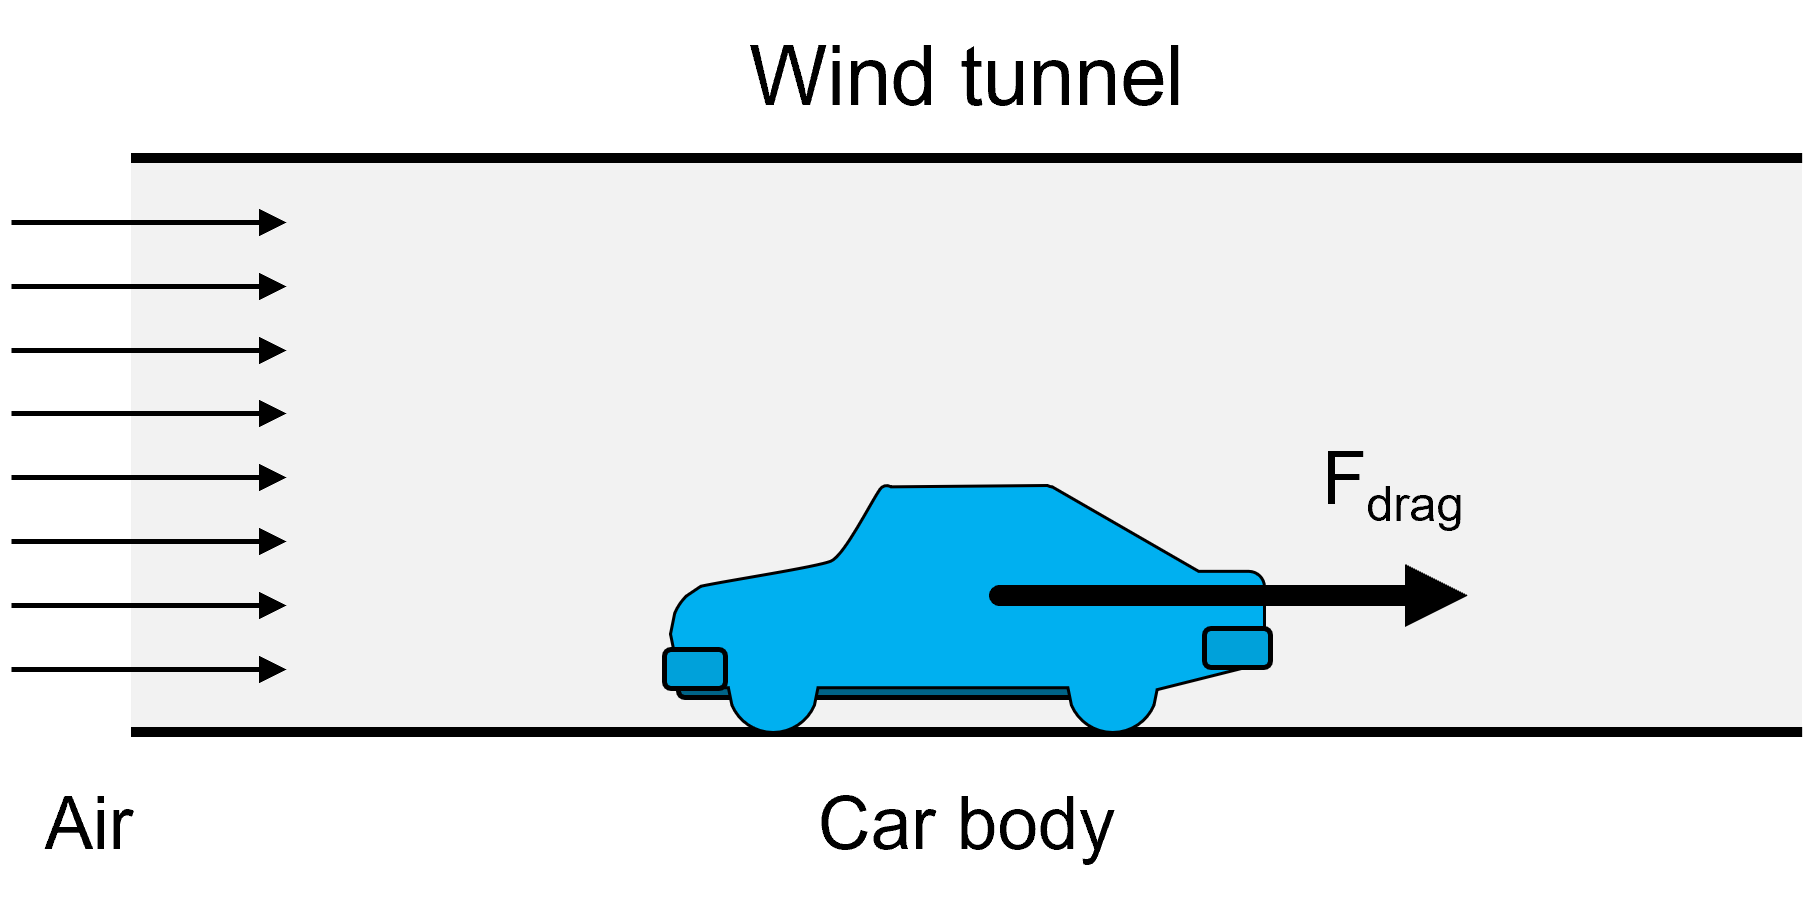

The drag force is related to the air velocity with the equation below

    
$$F_D =\frac{1}{2}\rho \;A\;C_D \;\;U^2$$


where

    $F_D$  -  Drag force on car body (measured in Newtons)

    $\rho \;$  -  Air density (1.2 kg/m^3)

    $A$  -  Car body frontal area (0.7 m^2)

    $C_D$  -  Drag coefficient

    $U$  -  Air velocity (measured in m/s)

## Task

The measured drag forces are stored in the `FDrag` vector and the corresponding air velocities are stored in the `U` vector. Follow the steps below to analyze the data to determine the car’s drag coefficient.

- Use the [`scatter`](https://www.mathworks.com/help/matlab/ref/scatter.html) function to create a scatter plot of the data with the freestream air velocity (`U`) on the x-axis and the drag force (`FDrag`) on the y-axis. Add axis labels to improve the plot’s readability. Note the nonlinear trend shown in the data.

- Fit a second-order polynomial to the data using the [`polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) function. Store the resulting polynomial coefficients in a new variable `coeffs`.

- Then, find the estimated drag force using the [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html) function to evaluate the polynomial at the values in the `U` vector. Store the result in a new variable `FDragEst`. 

- Overlay a line plot of the estimated drag force on top of the scatter plot created in Step 1. Hint: Remember to use the [`hold on`](https://www.mathworks.com/help/matlab/ref/hold.html) and `hold off` commands to overlay plots.

- Evaluate the equation below to calculate the car body's drag coefficient from the second-order polynomial. Store the result in a new variable `CD`.

                    $C_D =\frac{2}{\rho \;A}\cdot \;$`coeffs(1)`

You can use the car body's drag coefficient to gain a sense of how aerodynamic the vehicle is. Very aerodynamic vehicles can have values below 0.25, while most vehicles generally have values in the 0.25 to 0.35 range. 

### Setup Code

% Load the measured data (U and FDrag vectors)
load dragForceData.mat U FDrag

% Set the constant parameters
rho = 1.2;    % Air density (kg/m^3)
A = 0.7;      % Car body frontal area (m^2)

### Code

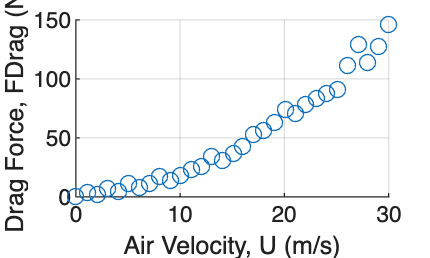

scatter(U, FDrag)
xlabel('Air Velocity, U (m/s)')
ylabel('Drag Force, FDrag (N)')
grid on


coeffs = polyfit(U, FDrag, 2)

coeffs =     0.1408    0.3794    1.9031


FDragEst = polyval(coeffs, U)

FDragEst =     1.9031
    2.4876
    3.3201
    4.3678
    5.8173
    7.4555
    9.4243
   11.5167
   14.0482
   16.8338
   19.9898
   23.3657
   27.0279
   30.8201
   35.2254


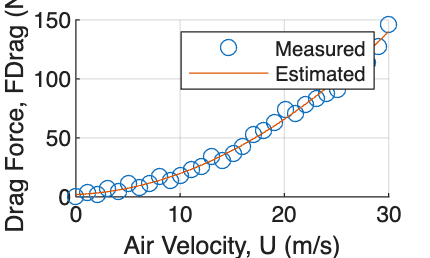

scatter(U, FDrag)
xlabel('Air Velocity, U (m/s)')
ylabel('Drag Force, FDrag (N)')
grid on

hold on
plot(U, FDragEst)
hold off

legend("Measured", "Estimated")

CD = 2/(rho * A) * coeffs(1)

CD = 0.3353

## Check your work

Is your code producing the expected results? 

Compare the values calculated by the code you wrote above to those listed below. Not seeing the output from your code? Remove the semicolons at the end of each line of code and run your code again to see the results.

Hints for common issues are provided below. If you still have questions, consider asking them in the course discussion forum.

**Task 1**

Visualize the data with a [`scatter`](https://www.mathworks.com/help/matlab/ref/scatter.html) plot, showing the freestream air velocity (`U`) on the x-axis and the drag force (`FDrag`) on the y-axis.

**Task 2**

`coeffs` should contain 3 values corresponding to the coefficients of a 2nd order polynomial.

- `coeffs: 0.1408    0.3794    1.9031`

Are your values different? If so, check the following:

- Use the [`polyfit`](https://www.mathworks.com/help/matlab/ref/polyfit.html) function to calculate a second-order fit to the drag and air velocity data. 

- The x input to `polyfit` should be the air velocity and the y input should be the drag force.

- Be sure to specify the correct order of the fit. 

**Task 3**

Use the [`polyval`](https://www.mathworks.com/help/matlab/ref/polyval.html) function to evaluate the polynomial in `coeffs` at all velocities in the `U` vector.

Are your values different? If so, check the following:

- The `first` input to `polyval` `should` be the polynomial coefficients. 

- The second input should be the x-values where the polynomial will be evaluated.

**Task 4**

Use the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) function to create a line plot with the freestream air velocity (`U`) on the x-axis and the estimated drag force (`FDragEst`) on the y-axis.

Hints:

- Use the [`hold on`](https://www.mathworks.com/help/matlab/ref/hold.html) command before calling `plot` to add a another plot to the existing scatter plot figure,

- It is best practice to also use the `hold off` command after the `plot` command.

**Task 5**

Evaluate the equation given in the problem statement to calculate the drag coefficient.

- `CD: 0.3353`

Are your values different? If so, check the following:

- The calculation is using the values of variables `rho` and `A` that have been defined at the top of the script.

- Use `indexing` to `access` the first polynomial coefficient: `coeffs(1)`.

## Conclusion

Congratulations on successfully completing this challenge activity! Continue your learning by returning to the course and marking this challenge complete, as shown in the image below.

    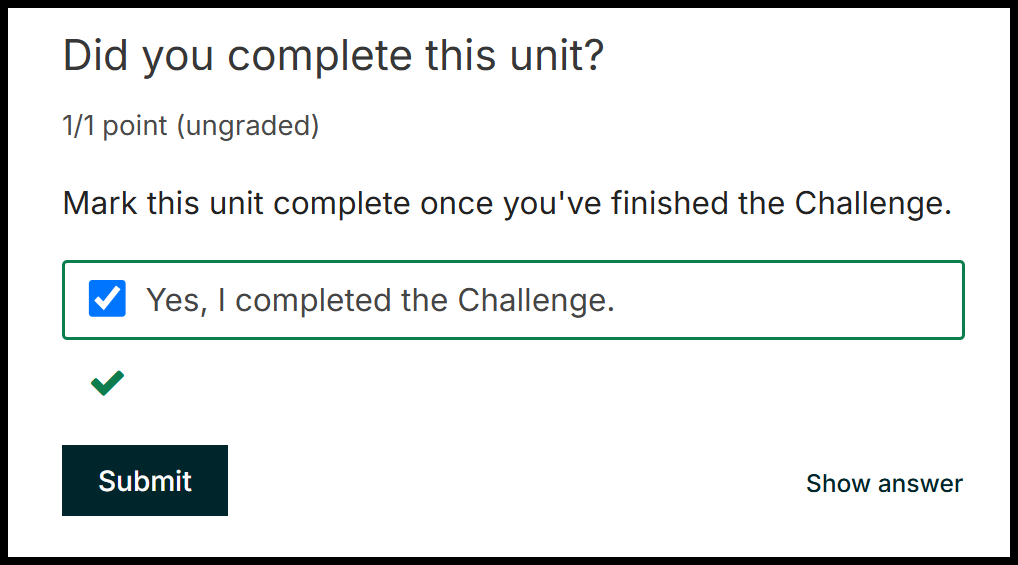

*Copyright 2025 The MathWorks, Inc.*